%Controlador proporcional integrante derivativo
%planta
num1 = [1];
den1 = [1 6 5 0];
Gp = tf(num1, den1);
%controlador
Kp = 39.42;
Ki = 5.8;
Kd = 13.84;
num2 = [Kd Kp Ki];
den2 = [1 0];
C = tf(num2, den2);
%função de transferencia do ramo direto
G = series(Gp, C)

G =
 
  13.84 s^2 + 18 s + 5.8
  ----------------------
   s^4 + 6 s^3 + 5 s^2
 
Continuous-time transfer function.
Model Properties


%função de trasnferencia de malha fechada
A = 1000;
FTMF = feedback(G,1)

FTMF =
 
         13.84 s^2 + 18 s + 5.8
  ------------------------------------
  s^4 + 6 s^3 + 18.84 s^2 + 18 s + 5.8
 
Continuous-time transfer function.
Model Properties


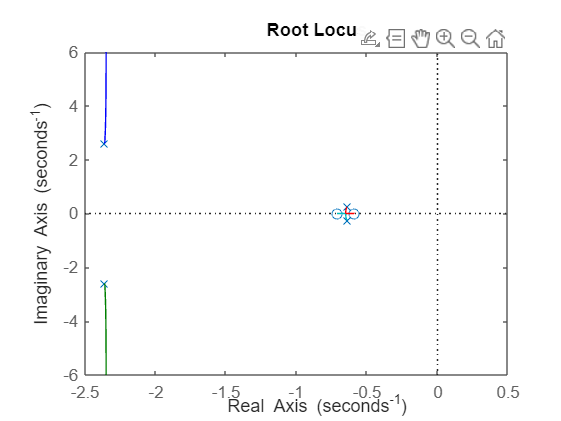

rlocus(FTMF)

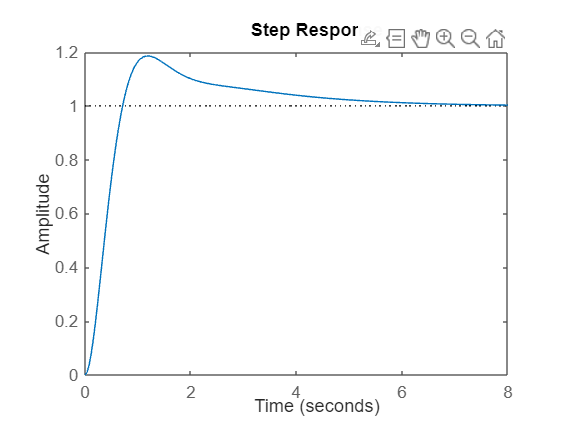

step(FTMF)